x_max = 55;
N_max_gr = 8;
gamma0 = 0;
gamma1 = 1;
gamma2 = 3;

x_eff = 11.8;
x_eff_real = 16;
psi = 0.96;
psi_real = 1.008;
A = [1.0075 1.0095 1.01]';
A_real = [1.0018 1.016 1.009]';
% I'm not going to bother writing out the group number bit since it will
% cancel with the 10
B = [1.65 2.07 2.47]';
B_real = [1.6969 2.2175 2.6709]';
lambda = 700;

x_con_init = [20 22 25 27 17]; 
x_aux_init = [6 6 7 7 8];

parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

parameters_pred = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff, ...
    'psi', psi, ...
    'A', A, ...
    'B', B, ...
    'lambda', lambda);


Np = 6;
parameters = parameters_real;

xk = [55;8];
[a,b,c] = functionForAll2(Np, xk, parameters, 0)

a =      0
     0


b = 0

c = 1000000

## 2.5) MPC

run = false;
if run
    Np = 6;
    % RUN 1 - Np = 6 - J_opt = 23805
    finduOpt = @(xk) functionForAll2(Np, xk, parameters_pred, -1);
    realUpdate = @(xk, uk) functionForAll2(Np, xk, parameters_real, uk);
    
    
    %[x_next, u_opt, J_opt] = realUpdate(xk, 0)
    
    T_end = 60; 
    
    xk_6 = zeros(2,5, T_end + 1); % xcon/xaux, section, time
    u_k_6 = zeros(5,T_end+1)
    xk_6(:, :, 1) = [x_con_init ; x_aux_init]; % Set initial conditions
    total_cost = 0;
    tic
    for i = 2:T_end+1
        disp("x_k = " + num2str(xk_6(:,:,i-1)))
        disp("time_elapsed = " + num2str(toc) + "seconds")
        disp("time step " + num2str(i-1) + " of " + num2str(T_end))
        for j = 1:5
            [~,u_k_6(j,i), ~] = finduOpt(xk_6(:,j,i-1)); 
            [xk_6(:,j,i), ~, J] = realUpdate(xk_6(:,j,i-1), u_k_6(j,i));
            total_cost = total_cost + J;
        end
    end
%{
    % RUN 2 - Np = 15 - J_opt = 23105
    Np = 15;
    finduOpt = @(xk) functionForAll2(Np, xk, parameters_pred, -1);
    realUpdate = @(xk, uk) functionForAll2(Np, xk, parameters_real, uk);
    
    
    %[x_next, u_opt, J_opt] = realUpdate(xk, 0)
    
    T_end = 60; 
    
    xk_15 = zeros(2,5, T_end + 1); % xcon/xaux, section, time
    u_k_15 = zeros(5,T_end+1);
    xk_15(:, :, 1) = [x_con_init ; x_aux_init]; % Set initial conditions
    total_cost = 0;
    tic
    for i = 2:T_end+1
        disp("x_k = " + num2str(xk_15(:,:,i-1)))
        disp("time_elapsed = " + num2str(toc) + "seconds")
        disp("time step " + num2str(i-1) + " of " + num2str(T_end))
        for j = 1:5
            [~,u_k_15(j,i), ~] = finduOpt(xk_15(:,j,i-1)); 
            [xk_15(:,j,i), ~, J] = realUpdate(xk_15(:,j,i-1), u_k_15(j,i));
            total_cost = total_cost + J;
        end
    end

%}
end



## 2.5a) Plotting data

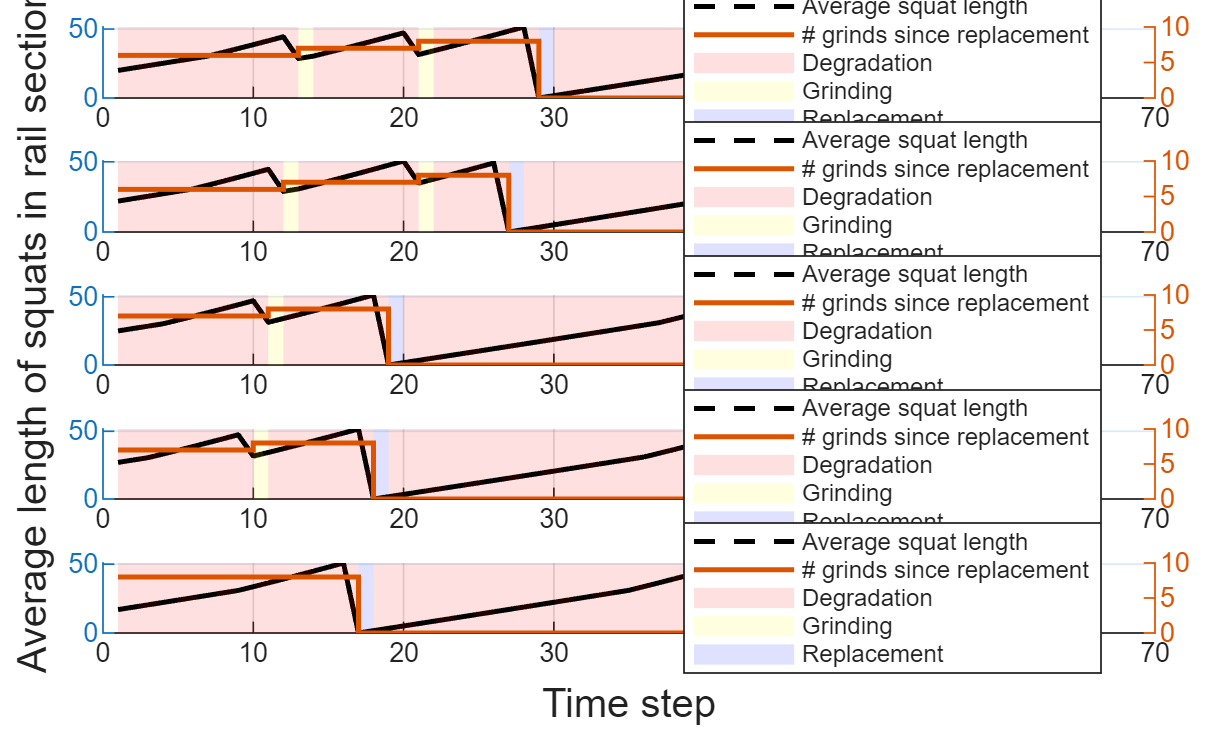

data = importdata("variables_2_5.mat");
u_k_15 = data.u_k_15;
u_k_6 = data.u_k_6;
xk_15 = data.xk_15;
xk_6 = data.xk_6;

T_end = 60;
t = 1:T_end+1;

figure;
bigPlot = tiledlayout(5,1,'TileSpacing','compact','Padding','compact');

xlabel(bigPlot,'Time step')
ylabel(bigPlot,'Average length of squats in rail section')
xk = xk_6; u_k = u_k_6;

for j = 1:5

    ax = nexttile;
    hold(ax,'on')
    grid(ax,'on')

    y_cont = squeeze(xk(1,j,:));
    y_disc = squeeze(xk(2,j,:));
    colour_state = squeeze(u_k(j,:));

    % ---------------------------
    % Continuous signal
    % ---------------------------
    yyaxis(ax,'left')
    h_cont = plot(ax,t,y_cont,'k','LineWidth',1.5);

    drawnow
    yl = ylim(ax);

    % ---------------------------
    % Background colour regions
    % ---------------------------
    for k = 1:length(t)-1

        switch colour_state(k)

            case 0
                c = [1 0 0]; % red

            case 1
                c = [1 1 0]; % yellow

            case 2
                c = [0 0 1]; % blue

            otherwise
                c = [0.8 0.8 0.8];
        end

        patch(ax,...
            [t(k) t(k+1) t(k+1) t(k)],...
            [yl(1) yl(1) yl(2) yl(2)],...
            c,...
            'FaceAlpha',0.12,...
            'EdgeColor','none',...
            'HandleVisibility','off');   % prevents legend duplication
    end

    % redraw line on top of patches
    yyaxis(ax,'left')
    h_cont = plot(ax,t,y_cont,'k','LineWidth',1.5);

    % ---------------------------
    % Discrete signal
    % ---------------------------
    yyaxis(ax,'right')
    h_disc = stairs(ax,t,y_disc,'LineWidth',1.5);

    % ---------------------------
    % Dummy objects for legend
    % ---------------------------
    h_red    = patch(nan,nan,[1 0 0],'FaceAlpha',0.12,'EdgeColor','none');
    h_yellow = patch(nan,nan,[1 1 0],'FaceAlpha',0.12,'EdgeColor','none');
    h_blue   = patch(nan,nan,[0 0 1],'FaceAlpha',0.12,'EdgeColor','none');

    % ---------------------------
    % Legend
    % ---------------------------
    legend(ax,...
        [h_cont h_disc h_red h_yellow h_blue],...
        {'Average squat length','# grinds since replacement',...
         'Degradation','Grinding','Replacement'},...
        'Location','best')

end

## FOr Np = 15

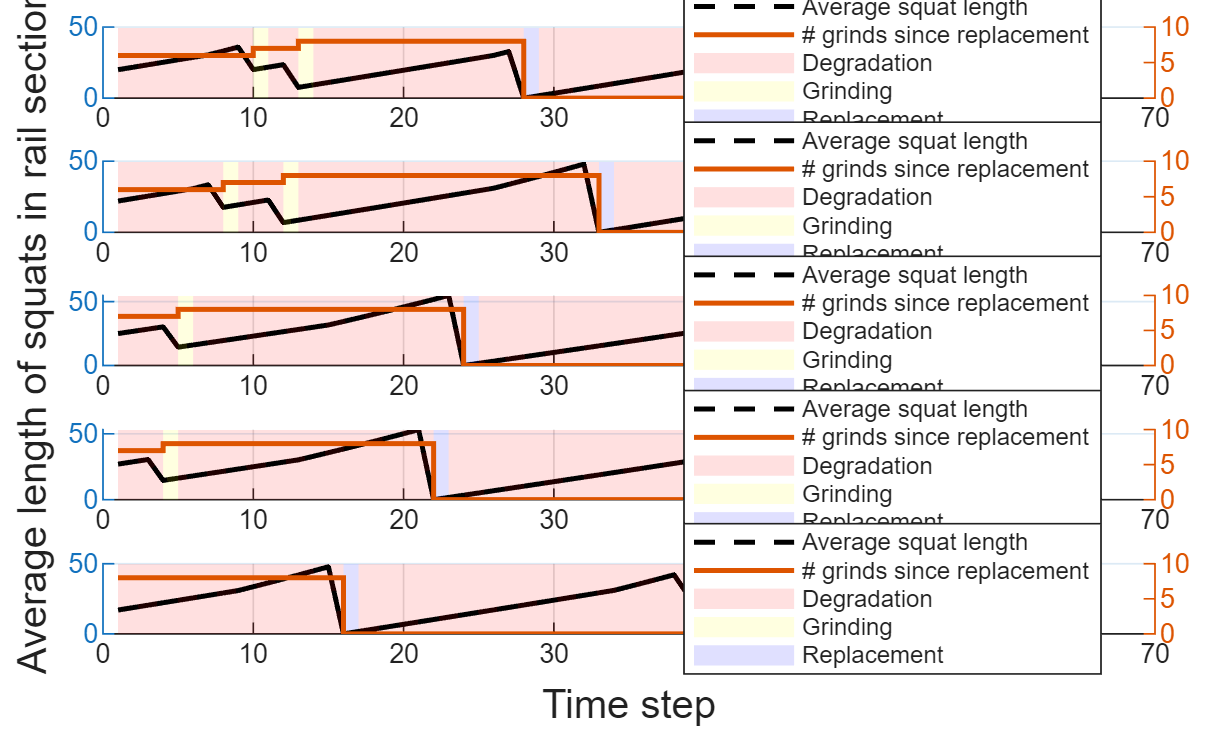

t = 1:T_end+1;

figure;
bigPlot = tiledlayout(5,1,'TileSpacing','compact','Padding','compact');

xlabel(bigPlot,'Time step')
ylabel(bigPlot,'Average length of squats in rail section')

xk = xk_15; u_k = u_k_15;

for j = 1:5

    ax = nexttile;
    hold(ax,'on')
    grid(ax,'on')

    y_cont = squeeze(xk(1,j,:));
    y_disc = squeeze(xk(2,j,:));
    colour_state = squeeze(u_k(j,:));

    % ---------------------------
    % Continuous signal
    % ---------------------------
    yyaxis(ax,'left')
    h_cont = plot(ax,t,y_cont,'k','LineWidth',1.5);

    drawnow
    yl = ylim(ax);

    % ---------------------------
    % Background colour regions
    % ---------------------------
    for k = 1:length(t)-1

        switch colour_state(k)

            case 0
                c = [1 0 0]; % red

            case 1
                c = [1 1 0]; % yellow

            case 2
                c = [0 0 1]; % blue

            otherwise
                c = [0.8 0.8 0.8];
        end

        patch(ax,...
            [t(k) t(k+1) t(k+1) t(k)],...
            [yl(1) yl(1) yl(2) yl(2)],...
            c,...
            'FaceAlpha',0.12,...
            'EdgeColor','none',...
            'HandleVisibility','off');   % prevents legend duplication
    end

    % redraw line on top of patches
    yyaxis(ax,'left')
    h_cont = plot(ax,t,y_cont,'k','LineWidth',1.5);

    % ---------------------------
    % Discrete signal
    % ---------------------------
    yyaxis(ax,'right')
    h_disc = stairs(ax,t,y_disc,'LineWidth',1.5);

    % ---------------------------
    % Dummy objects for legend
    % ---------------------------
    h_red    = patch(nan,nan,[1 0 0],'FaceAlpha',0.12,'EdgeColor','none');
    h_yellow = patch(nan,nan,[1 1 0],'FaceAlpha',0.12,'EdgeColor','none');
    h_blue   = patch(nan,nan,[0 0 1],'FaceAlpha',0.12,'EdgeColor','none');

    % ---------------------------
    % Legend
    % ---------------------------
    legend(ax,...
        [h_cont h_disc h_red h_yellow h_blue],...
        {'Average squat length','# grinds since replacement',...
         'Degradation','Grinding','Replacement'},...
        'Location','best')

end

## 2.6) Regular intervention (Genetic Algorithm)

function totalCost = doMe(var)
    x_max = 55;
    N_max_gr = 8;
    gamma0 = 0;
    gamma1 = 1;
    gamma2 = 3;
    
    x_eff_real = 16;
    psi_real = 1.008;
    A_real = [1.0018 1.016 1.009]';
    B_real = [1.6969 2.2175 1.6709]';
    lambda = 700;

    parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

    N_gr = var(1); M = round(var(2));
    xk = [20;0];
    Np = 1;
    T_end = M*(N_gr+1); 
    u = zeros(1,T_end);
    grind_IDs = M:M:T_end; u(grind_IDs) = 1;
    replacement_IDs = M*(N_gr+1):M*(N_gr+1):T_end; u(replacement_IDs) = 2;
    totalCost = 0;
    for i = 1:T_end
        [xk,~,J] = functionForAll2(Np, xk, parameters_real, u(i));
        totalCost = totalCost + J;
    end 
    totalCost = totalCost/T_end;
end

run2 = false;
if run2

    tic
    LB = [1,1]; UB = [8, 40];
    doMeNow = @doMe;
    N_M = ga(doMeNow, 2, zeros(1,2), 0, zeros(1,2) ,0, LB, UB, [], [1 2]); % [8; 9], 30 mins
    N_gr_opt = N_M(1);
    M = N_M(2);
    time = toc;

end



## 2.6a) Single run (once parameters established above)

function [x, us, totalCost] = doMe2(var, x0)
    x_max = 55;
    N_max_gr = 8;
    gamma0 = 0;
    gamma1 = 1;
    gamma2 = 3;
    
    x_eff_real = 16;
    psi_real = 1.008;
    A_real = [1.0018 1.016 1.009]';
    B_real = [1.6969 2.2175 1.6709]';
    lambda = 700;

    parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

    N_gr = var(1); M = round(var(2));
    xk = x0;
    Np = 1;
    T_end = M*(N_gr+1); 
    % Setup input sequence
    u = zeros(1,T_end);
    grind_IDs = M:M:T_end; u(grind_IDs) = 1;
    replacement_IDs = M*(N_gr+1):M*(N_gr+1):T_end; u(replacement_IDs) = 2;
    totalCost = 0;
    x = zeros(2,T_end);
    us = zeros(1,T_end);
    for i = 1:T_end
        [xk,u_current,J] = functionForAll2(Np, xk, parameters_real, u(i));
        totalCost = totalCost + J;
        x(:,i) = xk; us(i) = u_current;
    end 
    totalCost = totalCost/T_end;
end
x0 = [0;0];

[xs, us, J] = doMe2([8;9], x0)

xs =     1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610         0    1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610         0    1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610         0    1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610         0    1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610         0    1.6969    3.3969    5.0999    6.8059    8.5151
         0         0         0         0         0         0         0         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    5.0000    5.0000    5.0000    5.0000    5.0000    

us =      0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0


J = 95.0741

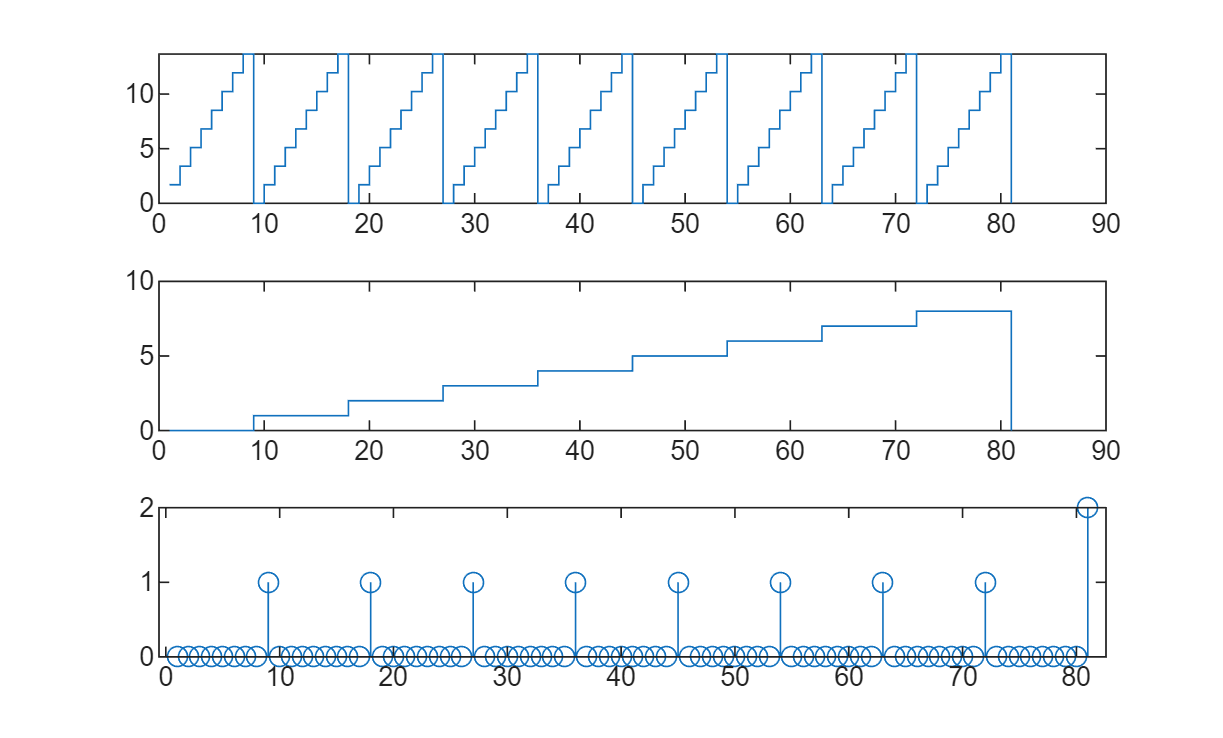


N = size(xs,2);
tiledlayout(3,1)
nexttile
stairs(1:N, xs(1,:));
nexttile
stairs(1:N, xs(2,:));
nexttile
stem(1:N, us(:));